依赖[统一实验分析作图v19.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

光声

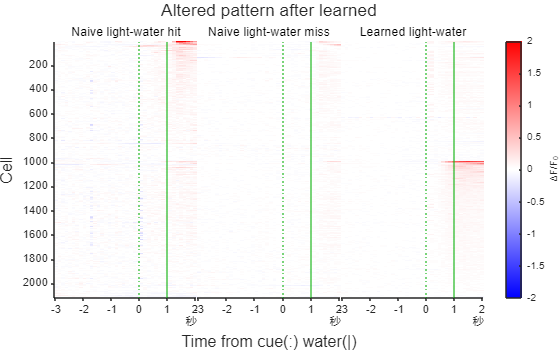

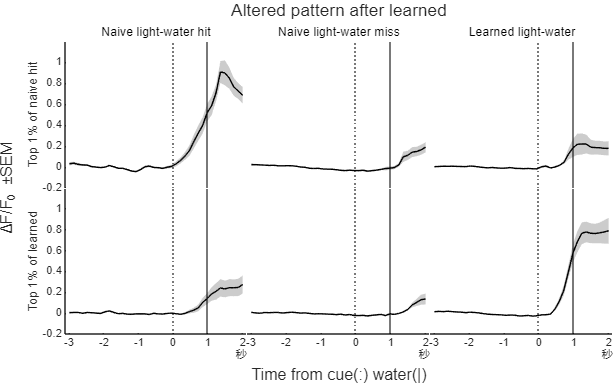

NumMice = 9

NumMice=Impl(bitor(TransferLearning.Flags.PPT,TransferLearning.Flags.LightAudio))

声光

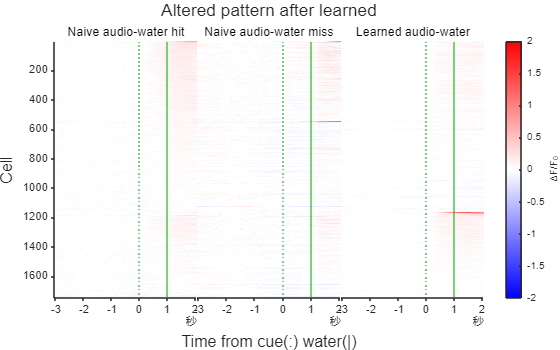

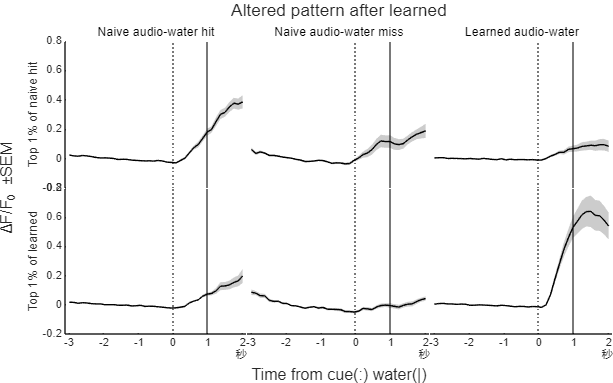

NumMice = 3

NumMice=Impl(bitor(TransferLearning.Flags.PPT,TransferLearning.Flags.AudioLight))

function NumMice=Impl(FigureFlag)
arguments
	FigureFlag
end
import TransferLearning.*
switch bitand(FigureFlag,Flags.Paradigm)
	case Flags.LightAudio
		SheetName='光声Naive命中错失';
		Stimulus='light-water';
	case Flags.AudioLight
		SheetName='声光Naive命中错失';
		Stimulus='audio-water';
	otherwise
		Exception.Unsupported_paradigm.Throw;
end
UniExpDataSet=memoize(@UniExp.DataSet);
DataSet=UniExpDataSet("\\Data-Server-2\个人数据\张天夫\202408\光声迁移MOp成像有穿插v2.精简版.mat");
DataSet.TrialSignals.ResampledSignal(:,41:end)=[];
DataSet=UniExp.DataSet.Merge(DataSet,TransferLearning.FullCalcium);
Calcium=UniExp.NtatsCellStrip(DataSet.QueryNTATS(UniExp.ReadQueryTable(ProjectPath('查询表.xlsx'),SheetName),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));
NumMice=numel(unique(DataSet.Cells.Mouse(ismember(DataSet.Cells.CellUID,Calcium.CellUID))));
SubTitles=compose(["Naive %s hit","Naive %s miss","Learned %s"],Stimulus);
Layout=BasicHeatmap(UniExp.HeatmapSort(Calcium,["Naive_hit","Learned"]).NTATS{:,:,["Naive_hit","Naive_miss","Learned"]},SubTitles,GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]),false,CLim=[-2,2]);
Target=Flags(bitand(FigureFlag,Flags.Target));
switch Target
	case Flags.Article
		title(Layout,sprintf('MOp2/5, %u cells, %u mice',height(Calcium),numel(unique(DataSet.Cells.Mouse(ismember(DataSet.Cells.CellUID,Calcium.CellUID))))));
		MATLAB.Graphics.FigureAspectRatio(1,2,MATLAB.Flags.Amplify);
	case Flags.PPT
		title(Layout,'Altered pattern after learned');
		MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
	otherwise
		Exception.Unsupported_target.throw;
end
print(ProjectPath(sprintf('%s.热图.%s.svg',SheetName,Target)),'-dsvg');

取 Naive hit 和Learned前1%强细胞

Index5P=1:uint8(height(Calcium)/100);
[~,SortIndex]=sort(sum(Calcium.NTATS.Naive_hit,2),'descend');
NaiveData=Calcium(SortIndex(Index5P),:).NTATS(:,:,["Naive_hit","Naive_miss","Learned"]);
[NaiveMean,NaiveSem]=MATLAB.DataFun.MeanSem(NaiveData.Data,1);
[~,SortIndex]=sort(sum(Calcium.NTATS.Learned,2),'descend');
LearnedData=Calcium(SortIndex(Index5P),:).NTATS(:,:,["Naive_hit","Naive_miss","Learned"]);
[LearnedMean,LearnedSem]=MATLAB.DataFun.MeanSem(LearnedData.Data,1);
Xs=seconds(linspace(-3,2,size(NaiveMean,2)))';

作三种条件下的曲线

figure;
Layout=tiledlayout(2,3,TileSpacing='none',Padding='tight');
Axes=gobjects(2,3);
for A=1:3
	Axes(1,A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(NaiveMean(:,:,A)',NaiveSem(:,:,A)',X=Xs,EdgeColors=[0,0,0]);
	xline(0,':k');
	xline(1,'-k');
	title(SubTitles(A));
	Axes(1,A).XAxis.Visible='off';
	if A>1
		Axes(1,A).YAxis.Visible='off';
	end
end
for A=1:3
	Axes(2,A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(LearnedMean(:,:,A)',LearnedSem(:,:,A)',X=Xs,EdgeColors=[0,0,0]);
	xline(0,':k');
	xline(1,'-k');
	if A>1
		Axes(2,A).YAxis.Visible='off';
	end
end
ylabel(Axes(1,1),'Top 1% of naive hit');
ylabel(Axes(2,1),'Top 1% of learned');
xlabel(Layout,'Time from cue(:) water(|)');
ylabel(Layout,'ΔF/F_0 ±SEM');
MATLAB.Graphics.UnifyAxesLims(Axes,@ylim);
MATLAB.Graphics.FigureAspectRatio(8,5,1);
switch Target
	case Flags.Article
		title(Layout,sprintf('MOp2/5 %u cells',numel(Index5P)));
	case Flags.PPT
		title(Layout,'Altered pattern after learned');
	otherwise
		Exception.Unsupported_target.throw;
end
print(ProjectPath(sprintf('%s.线图.%s.svg',SheetName,Target)),'-dsvg');
end